clear
clc
% system("g++ main.cpp -o main.exe -O2");
% system("main.exe --elemType hex8 --remesh --stress");
% system("main.exe --elemType hex8 --remesh");
% system("main.exe --elemType hex8 --stress");
% system("main.exe --elemType hex8");

fg_w = 600;
fg_h = 600;

nodeCoords = readmatrix("nodeCoords.txt");
hexaCon = readmatrix("hexaCon.txt","NumHeaderLines",0);

if isnan(hexaCon(1,3))
    hexaCon = hexaCon(2:end,:);
else
    nElems = hexaCon(1,1);
    nx = hexaCon(1,3);
    ny = hexaCon(1,4);
    nz = hexaCon(1,5);
    hexaCon = hexaCon(2:end,:);
end

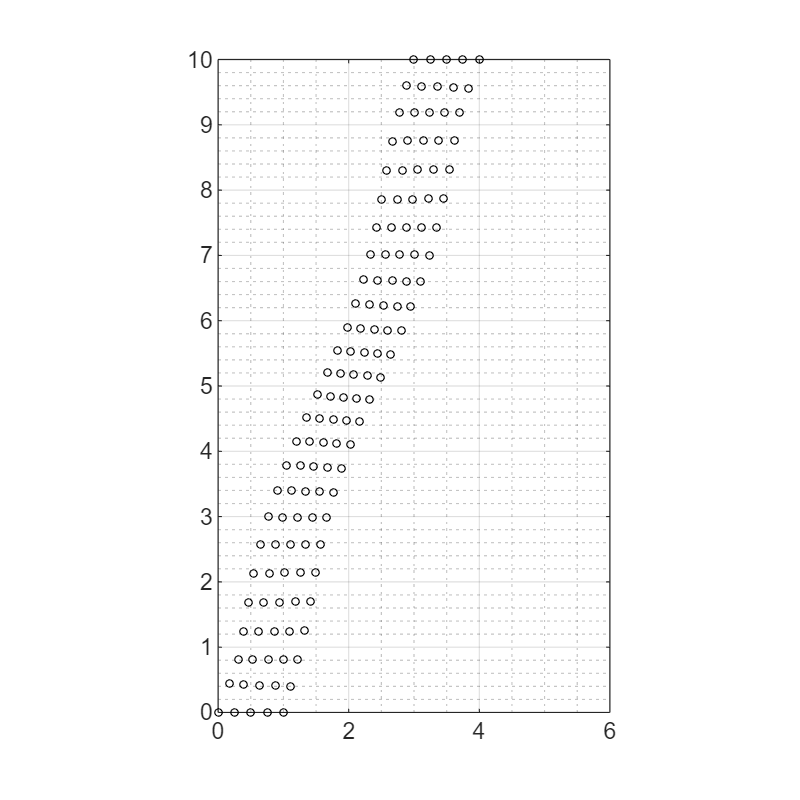

dof = readmatrix("dof_vector.txt");
nDOFs = max(dof(:,2)) + 3;
freeDOFs = dof(1,2);
fixedDOFs = nDOFs - freeDOFs;
dof = dof(2:end,2) + 1;

u_ff_ = readmatrix("u_free.txt")';
u_fs_ = readmatrix("u_fixed.txt")';

t_range = u_ff_(1,:);

fg = figure("Position",[0,0,fg_w,fg_h]);
for t = 1:length(t_range)
    u_ff = u_ff_(2:end,t);
    u_fs = u_fs_(2:end,t);
    u = [u_ff;u_fs];

    for i = 1:length(nodeCoords)
        ux(i) = u(dof(i)); %#ok
        uy(i) = u(dof(i)+1); %#ok
        uz(i) = u(dof(i)+2); %#ok
    end

    for j = 1:size(hexaCon,1)
        for i = 1:size(hexaCon,2)
            x(i,1) = nodeCoords(hexaCon(j,i),2) + ux(hexaCon(j,i)); %#ok
            y(i,1) = nodeCoords(hexaCon(j,i),3) + uy(hexaCon(j,i)); %#ok
            z(i,1) = nodeCoords(hexaCon(j,i),4) + uz(hexaCon(j,i)); %#ok
            pGroup(i,1) = nodeCoords(hexaCon(j,i),5); %#ok
        end
        scatter3(x,y,z,10,'k') % Nodes
        hold on
    end
    hold off
    grid minor
    box on
    axis equal
    xlim([0,6])
    ylim([0,10])
    view([0,90])

    frame(t) = getframe(fg); %#ok
end

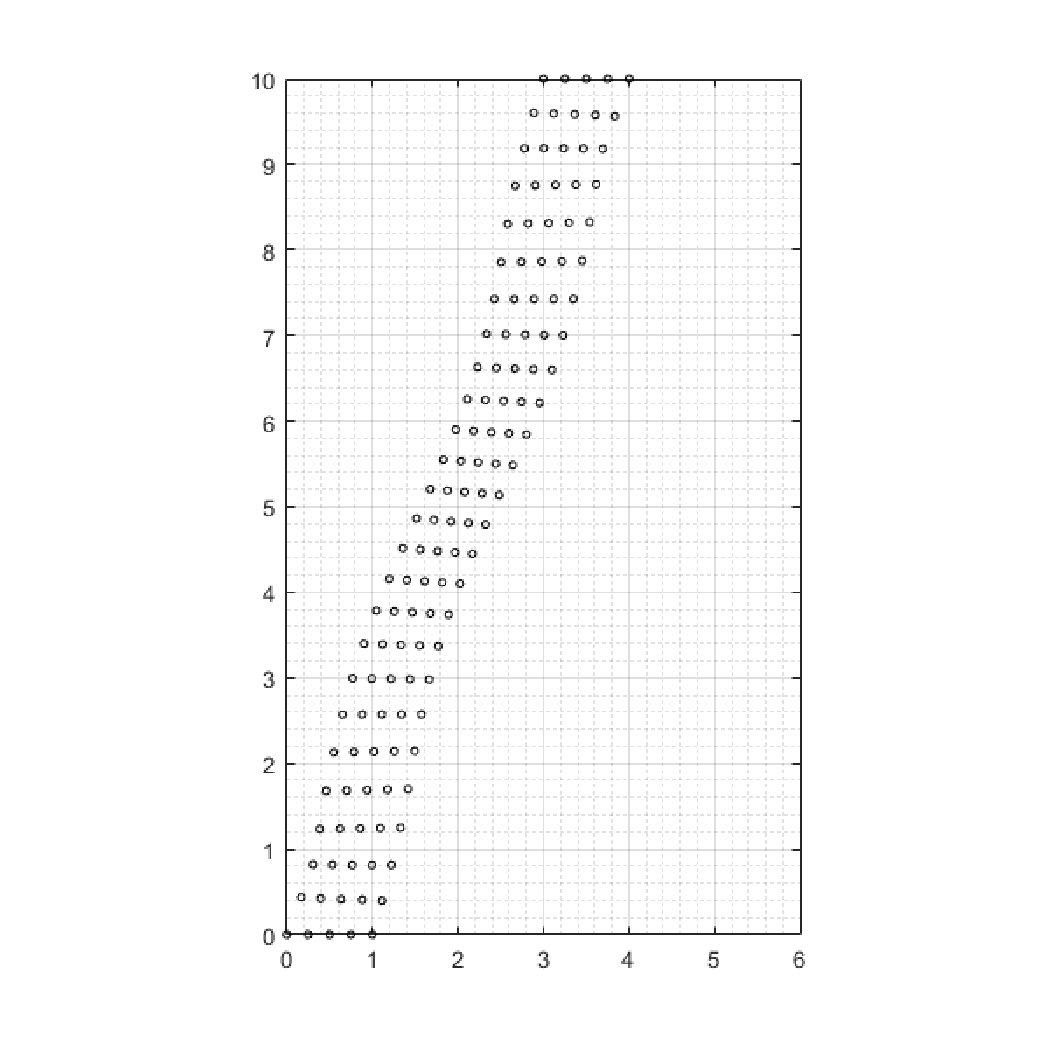

fg = figure("Position",[0,0,fg_w,fg_h]);
movie(fg,frame,2)